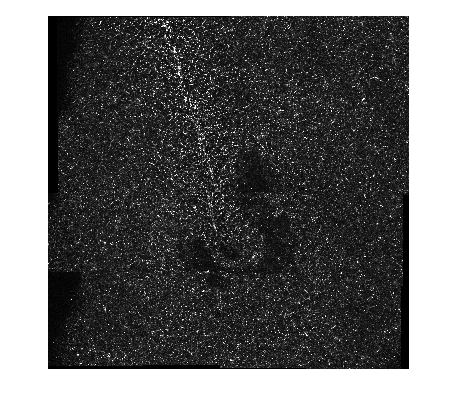

im_confocal_m=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C2-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_m,[]);

im_confocal_a=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C3-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_a,[]);


DLSM_pixel=.65 ;%microns
confocal_pixel = 1/5.548 ;
confocal_tile = @(x) round(x*DLSM_pixel/confocal_pixel); %to get 
%equivalent tile size to 180, 256, etc pixel tiles on DLSM images

tile_size_DSLM=16;
tile_size_confocal=confocal_tile(tile_size_DSLM)

tile_size_confocal = 58

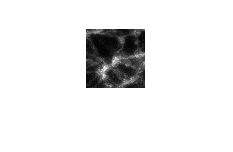

loc1 = [3500,220]; %in upper right uniform area
tile1a = im_confocal_a(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1a,[])

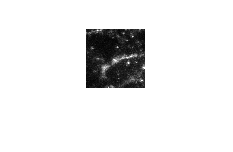

tile1m = im_confocal_m(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1m,[])

FT = @(x) abs(fftshift(fft2(perdecomp(x))));

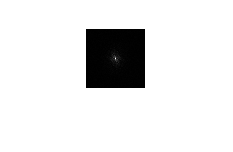

imshow(FT(tile1a),[0,100000])

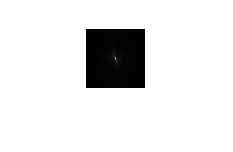

imshow(FT(tile1m),[0,100000])

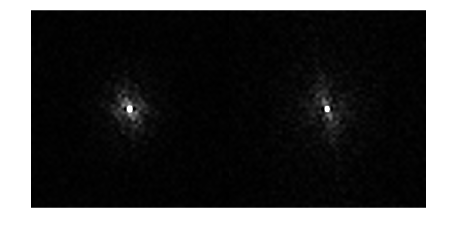

montage({FT(tile1a), FT(tile1m)},[], DisplayRange=[0,50000])

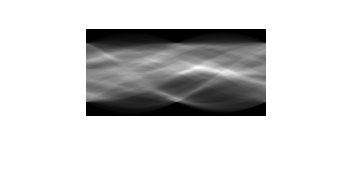

imshow(radon(tile1a),[])

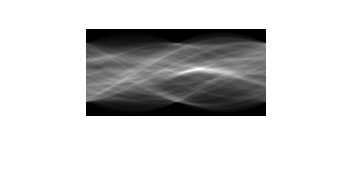

imshow(radon(tile1m),[])

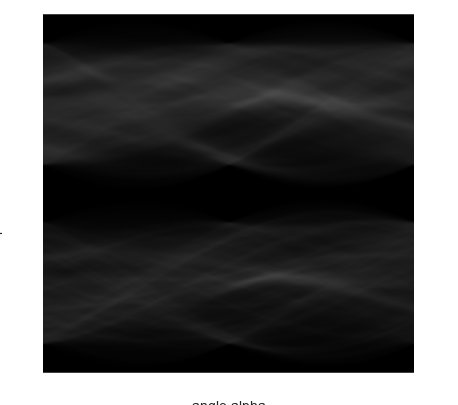

montage({radon(tile1a), radon(tile1m)},[], DisplayRange=[1,25000])
xlabel("angle alpha")
ylabel("position delta")

mask = zeros(size(tile1a))

mask =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

xlen=size(tile1a,1)

xlen = 59

ylen=size(tile1a,2)

ylen = 59

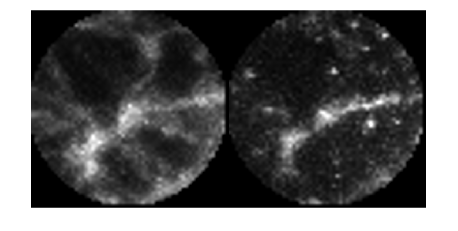

for x=1:xlen
    for y = 1:ylen
        if sqrt((x-xlen/2)^2+(y-ylen/2)^2) < min(size(tile1a))/2
            mask(x,y)=1;
        end
    end
end
circle1a= double(tile1a).*mask;
circle1m= double(tile1m).*mask;
montage({circle1a, circle1m}, [], displayRange=[0,255])

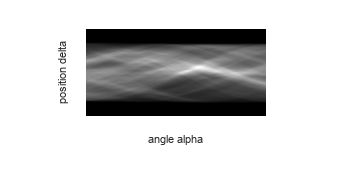

imshow(radon(circle1a),[])
xlabel("angle alpha")
ylabel("position delta")

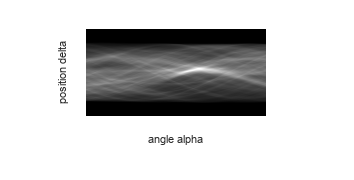

imshow(radon(circle1m),[])
xlabel("angle alpha")
ylabel("position delta")

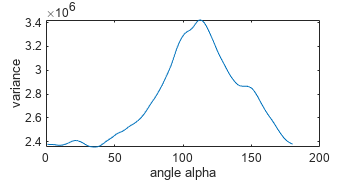

angles1a = radon(circle1a);
var1a = var(angles1a, [], 1);
angles1m = radon(circle1m);
var1m = var(angles1m, [], 1);
plot(var1a)
xlabel("angle alpha")
ylabel("variance")

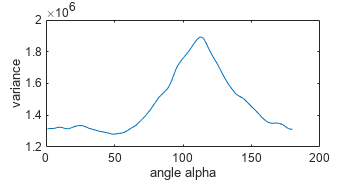

plot(var1m)
xlabel("angle alpha")
ylabel("variance")

[variance, ang]=max(var1a);
xo=xlen/2;
yo=ylen/2;
ang = deg2rad(-ang+90)

ang = -0.4014

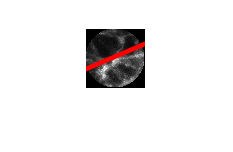

x1 = xo+cos(ang)*100; 
y1 = yo+sin(ang)*100;
x2 = xo-cos(ang)*100;
y2 = yo-sin(ang)*100;
%circle1a_2=imadjust(circle1a);
circle1a_red = insertShape(cast(circle1a, "uint8"), 'line', [x1 y1 x2 y2], 'LineWidth', 5, 'Color', [255,0,0]);
imshow(circle1a_red, [0,255])

[variance, ang]=max(var1m);
xo=xlen/2;
yo=ylen/2;
ang = deg2rad(-ang+90)

ang = -0.4014

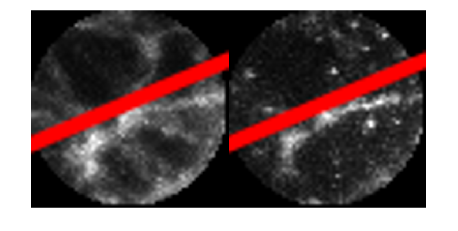

x1 = xo+cos(ang)*100; 
y1 = yo+sin(ang)*100;
x2 = xo-cos(ang)*100;
y2 = yo-sin(ang)*100;
%circle1a_2=imadjust(circle1a);
circle1m_red = insertShape(cast(circle1m, "uint8"), 'line', [x1 y1 x2 y2], 'LineWidth', 5, 'Color', [255,0,0]);
montage({circle1a_red, circle1m_red})